datastore = CLIPDatastore(ImageFolder="./flickr-dataset/Flicker8k_Dataset");
ds = shuffle(datastore, "PercentageToKeep", 0.1)

ds =   CLIPDatastore with no properties.


disp("Number of training images " + numel(ds))

Number of training images 4045


[net,tokenizer] = bert();

r = read(ds)

r = 1×3 cell array
    {375×500×3 uint8}    {[102 1038 2830 1999 2318 3900 2023 3234 2007 1038 3510 2008 1038 5094 3609 3876 2010 1013 103]}    {["A brown and white dog be stand on a beach with a tennis ball beside it ."]}


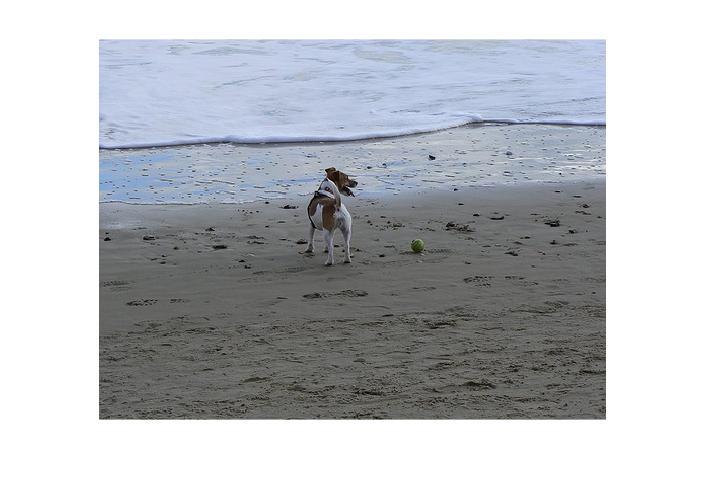

[im, tokens, caption] = r{:};
imshow(im)

%caption = "A group of horse and their rider be race each other .";
[~, segments] = encode(tokenizer, caption);

dltoken = dlarray(tokens, 'CT');
dlsegment = dlarray(segments{1}, 'CT');
mask = dlarray(ones(1, numel(dlsegment)), 'CT');

pred = predict(net, dltoken, mask, dlsegment);

decodedTokens = decode(tokenizer, tokens)

decodedTokens = "[CLS] a brown and white dog be stand on a beach with a tennis ball beside it . [SEP]"

disp(size(pred))

   768    19



last = pred(:,1) % Use the [CLS] token but the official CLIP implementation trained their own text encoder and used the last token's embedding

last =   768(C) × 1(T) single dlarray

   -0.1619
    0.1122
    0.0165
    0.2698
    0.4631
   -0.1553
   -0.8530
   -0.2024
    0.9055
   -0.6768
   -0.7652
   -0.0726
    0.1286
   -0.1564
    0.2780
   -0.6613
   -0.0843
    0.1238
   -0.2511
    0.0625
    0.9421
    0.3946
    0.9486
   -0.1518
    0.3096
   -0.0485
   -0.1530
   -0.3189
   -0.0605
    0.3506
   -0.0502
    0.0719
   -0.8412
    0.0762
   -0.2313
    0.3087
    0.1102
    0.2259
    0.0790
   -0.4489
   -0.1205
   -0.4641
    0.0662
    0.1291
   -0.0177
    0.0010
   -0.4784
    0.8980
   -0.3849
    0.3595
   -0.8618
   -0.0130
    0.2654
   -0.0317
   -0.1124
    0.2808
    0.7873
   -0.1377
   -0.3357
    0.1724
    0.4571
   -0.1736
   -0.3651
   -0.3900
    0.4231
    0.1102
    0.1725
   -0.1159
    0.4088
    0.0058
   -0.2348
    0.4472
   -0.9887
   -0.0408
   -0.0838
   

% NB: Using Bert for batched prediction
[net, tokenizer] = bert() %bert("Model","tiny");

net =   dlnetwork with properties:

         Layers: [129×1 nnet.cnn.layer.Layer]
    Connections: [164×2 table]
     Learnables: [197×3 table]
          State: [0×3 table]
     InputNames: {'input_ids'  'attention_mask'  'seg_ids'}
    OutputNames: {'enc12_layernorm2'}
    Initialized: 1

  View summary with summary.


tokenizer =   bertTokenizer with properties:

        IgnoreCase: 1
      StripAccents: 1
      PaddingToken: "[PAD]"
       PaddingCode: 1
        StartToken: "[CLS]"
         StartCode: 102
      UnknownToken: "[UNK]"
       UnknownCode: 101
    SeparatorToken: "[SEP]"
     SeparatorCode: 103
       ContextSize: 512


paddingValue = tokenizer.PaddingCode;
str = [
    "Coolant is pooling underneath sorter."
    "Sorter blows fuses at start up."
    "There are some very loud rattling sounds coming from the assembler."];
[inputIdsStr, segmentIdsStr] = encode(tokenizer, str);

% The `maskStr` is used to specify the indices of the `paddingValue` so
% that the model ignores the padding
[inputIdsStr, maskStr] = padsequences(inputIdsStr, 2,"PaddingValue",paddingValue);
segmentIdsStr = padsequences(segmentIdsStr, 2,"PaddingValue",paddingValue);

inputIdsStr = dlarray(inputIdsStr, "CTB");
maskStr = dlarray(maskStr, "CTB");
segmentIdsStr = dlarray(segmentIdsStr, "CTB");

predictions = predict(net,inputIdsStr,maskStr,segmentIdsStr);

net = imageEncoder();
randX = dlarray(randn(net.Layers(1).InputSize), 'SSC');
net = dlnetwork(net, randX);
out = predict(net, randX);
disp(size(out))

      100352           1



net = textEncoder();
randX = dlarray(randn(1,1,10), 'CBT');
net = dlnetwork(net, Initialize=false);
net = initialize(net, randX, randX, randX)

net =   dlnetwork with properties:

         Layers: [1×1 nnet.cnn.layer.NetworkLayer]
    Connections: [0×2 table]
     Learnables: [37×3 table]
          State: [0×3 table]
     InputNames: {'bert_encoder/bert_model/input_ids'  'bert_encoder/bert_model/attention_mask'  'bert_encoder/bert_model/seg_ids'}
    OutputNames: {'bert_encoder'}
    Initialized: 1

  View summary with summary.



randInputIDs = dlarray(randi(1000, [1 3 10]), 'CBT');
attentionMask = dlarray(ones(size(randInputIDs)), 'CBT');
segmentIDs = dlarray(ones(size(randInputIDs)), 'CBT');

out = predict(net, randInputIDs, attentionMask, segmentIDs);
clsEmbeddings = out(:,:,1);

projHead = projectionHead();
net = dlnetwork(projHead, dlarray(randn(1,2048), 'BC'))

net =   dlnetwork with properties:

         Layers: [1×1 nnet.cnn.layer.NetworkLayer]
    Connections: [0×2 table]
     Learnables: [4×3 table]
          State: [0×3 table]
     InputNames: {'proj'}
    OutputNames: {'proj'}
    Initialized: 1

  View summary with summary.


out = predict(net, dlarray(randn(1,2048), 'BC'));
size(out)

ans =    256     1


## CLIP Interface

load net-gpu-poor-squeezenet-bert-tiny.mat net logTemperature

imageInputSize = net.Layers(1).Layers(1).InputSize(1:2);
clip = CLIP(net, Temperature=exp(logTemperature), ImageInputSize=imageInputSize)

clip =   CLIP with no properties.


% Try encoding some images

% First gather all image paths from the dataset
imgBaseDir = "./flickr-dataset/Flicker8k_Dataset/";
folderContents = dir(imgBaseDir);
boolImagesInFolder = arrayfun(@(x) ~x.isdir, folderContents);
folderContents = folderContents(boolImagesInFolder);
imagePaths = arrayfun(@(s) fullfile(s.folder, s.name), folderContents, UniformOutput=false)

imagePaths = 8091×1 cell array
    {'/home/aibrahee/Documents/openai-clip-matlab/flickr-dataset/Flicker8k_Dataset/1000268201_693b08cb0e.jpg'}
    {'/home/aibrahee/Documents/openai-clip-matlab/flickr-dataset/Flicker8k_Dataset/1001773457_577c3a7d70.jpg'}
    {'/home/aibrahee/Documents/openai-clip-matlab/flickr-dataset/Flicker8k_Dataset/1002674143_1b742ab4b8.jpg'}
    {'/home/aibrahee/Documents/openai-clip-matlab/flickr-dataset/Flicker8k_Dataset/1003163366_44323f5815.jpg'}
    {'/home/aibrahee/Documents/openai-clip-matlab/flickr-dataset/Flicker8k_Dataset/1007129816_e794419615.jpg'}
    {'/home/aibrahee/Documents/openai-clip-matlab/flickr-dataset/Flicker8k_Dataset/1007320043_627395c3d8.jpg'}
    {'/home/aibrahee/Documents/openai-clip-matlab/flickr-dataset/Flicker8k_Dataset/1009434119_febe49276a.jpg'}
    {'/home/aibrahee/Documents/openai-clip-matlab/flickr-dataset/Flicker8k_Dataset/1012212859_01547e3f17.jpg'}
    {'/home/aibrahee/Documents/openai-clip-matlab/flickr-dataset/Flicker8k_Datase

allImagePaths = string(imagePaths);

% Get some random images from the dataset
someImagePaths = randsample(allImagePaths, 20);
% Intentionally duplicate the last image
%someImagePaths(end+1) = someImagePaths(end);

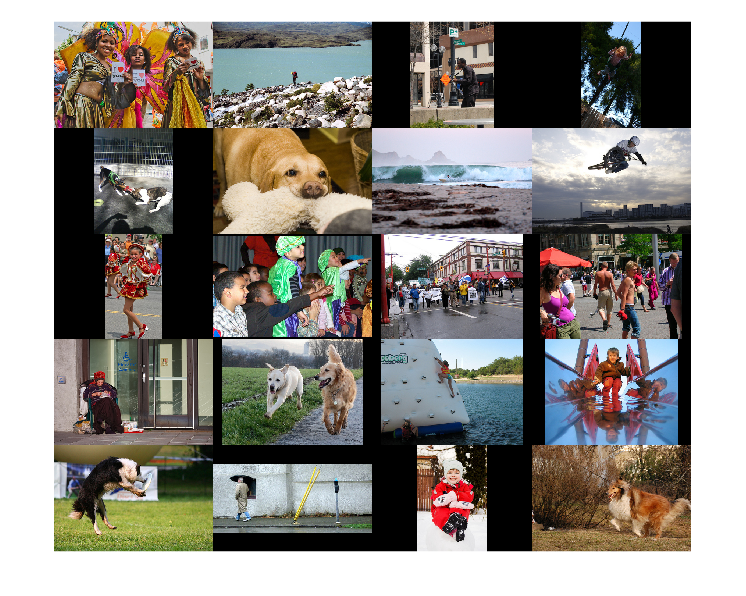

%imshow(imread(someImagePaths(1)));
images = arrayfun(@(x) imread(x), someImagePaths, UniformOutput=false);
montage(images)

%imageEmbeddings = clip.encodeImagesAt(someImagePaths);
[probs, logits] = clip.predict(someImagePaths, ["two Dogs", "Sea"]);
disp(probs)

  20×2 single gpuArray dlarray

    0.0000    0.0001
    0.0000    0.0892
    0.0000    0.0000
    0.0000    0.0000
    0.5766    0.0000
    0.0130    0.0001
    0.0000    0.8127
    0.0000    0.0006
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0001
    0.0000    0.0000
    0.3801    0.0000
    0.0000    0.0909
    0.0000    0.0000
    0.0008    0.0000
    0.0000    0.0007
    0.0000    0.0000
    0.0295    0.0056



[maxProb, maxIdx] = max(extractdata(gather(probs)));
disp("Query Match Probability: " + maxProb)

    "Query Match Probability: 0.57656"    "Query Match Probability: 0.8127"



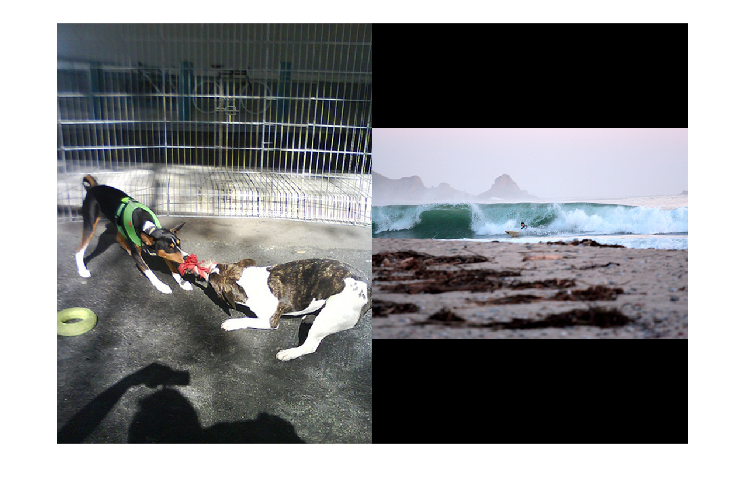


maxImages = {};
for idx=1:numel(maxIdx)
    maxImages{end+1} = imread(someImagePaths(maxIdx(idx)));
end
montage(maxImages)

% im2imLogits = imageEmbeddings' * imageEmbeddings * 40; % temperature of 100
% im2imProbs = softmax(im2imLogits, "DataFormat", "SC")
% % Visually check that the last 2x2 submatrix is not equal to 1, should be
% % around 0.5
% disp("The last 2 duplicated images")
% im2imProbs(end-1:end, end-1:end)